# Logistic Regression

The logistic regression **hypothesis** is defined as:


$$h_\theta(x)=g\left(\theta^T x\right)$$


The **sigmoid function** is defined as:


$$g(z)=\frac{1}{1+e^{-z}}$$


The **cost function** in logistic regression is:


$$J(\theta)=\frac{1}{m} \sum_{i=1}^m\left[-y^{(i)} \log \left(h_\theta\left(x^{(i)}\right)\right)-\left(1-y^{(i)}\right) \log \left(1-h_\theta\left(x^{(i)}\right)\right)\right]$$


The **gradient** of the cost:


$$\frac{\partial J(\theta)}{\partial \theta_j}=\frac{1}{m} \sum_{i=1}^m\left(h_\theta\left(x^{(i)}\right)-y^{(i)}\right) x_j^{(i)}$$


**Regularized logistic regression**

The regularized cost function in logistic regression is:


$$J(\theta)=\frac{1}{m} \sum_{i=1}^m\left[-y^{(i)} \log \left(h_\theta\left(x^{(i)}\right)\right)-\left(1-y^{(i)}\right) \log \left(1-h_\theta\left(x^{(i)}\right)\right)\right]+\frac{\lambda}{2 m} \sum_{j=1}^n \theta_j^2$$


The gradient of the cost function is a vector where the *j *th element is defined as follows: 


$$\frac{\partial J(\theta)}{\partial \theta_0}=\frac{1}{m} \sum_{i=1}^m\left(h_\theta\left(x^{(i)}\right)-y^{(i)}\right) x_j^{(i)} \quad \text { for } j=0$$



$$\frac{\partial J(\theta)}{\partial \theta_j}=\frac{1}{m} \sum_{i=1}^m\left(h_\theta\left(x^{(i)}\right)-y^{(i)}\right) x_j^{(i)}+\frac{\lambda}{m} \theta_j \quad \text { for } j \geq 1$$


## **1 Logistic Regression**

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. 

Suppose that you are the administrator of a university department and you want to determine each applicant’s chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant’s scores on two exams and the admissions decision. 

clear; close all; clc;

data = load('ex2data1.txt');
X_raw = data(:, [1, 2]); 
y = data(:, 3);

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X_raw);

% Add intercept term to x and X_test
X = [ones(m, 1) X_raw];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


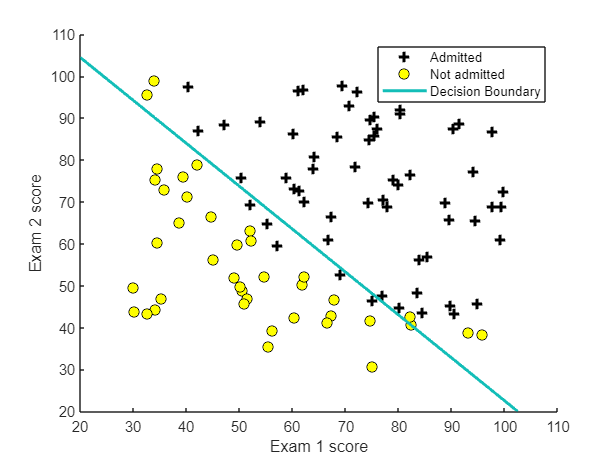

% Visualizing the data and the decision boundary
figure
hold on;
pos = find(y==1); 
neg = find(y==0);
plot(X_raw(pos, 1), X_raw(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
plot(X_raw(neg, 1), X_raw(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);

% plot_x = [min(X(:,2))-2,  max(X(:,2))+2];
% plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));
% plot(plot_x, plot_y)

u = linspace(20, 110, 200);
v = linspace(20, 110, 200);
z = zeros(length(u), length(v));
% Evaluate z = theta*x over the grid
for i = 1:length(u)
    for j = 1:length(v)
        z(i,j) = [1, u(i), v(j)]*theta;
    end
end
z = z'; % important to transpose z before calling contour
contour(u, v, z, [0, 0], 'LineWidth', 2)    % specify the range [0, 0]

legend('Admitted', 'Not admitted', 'Decision Boundary')
xlabel('Exam 1 score')
ylabel('Exam 2 score')
hold off;

## 2 **Regularized logistic regression**

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. 

Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model. 

clear;

data = load('ex2data2.txt');
X_raw = data(:, [1, 2]); 
y = data(:, 3);

X = mapFeature(X_raw(:,1), X_raw(:,2));

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 83.050847


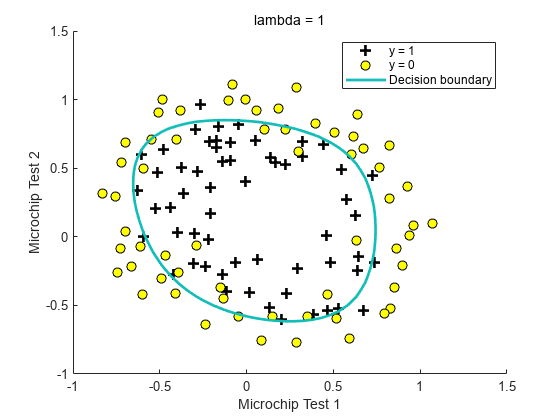

% Visualizing the data and the decision boundary
figure
hold on;
pos = find(y==1); 
neg = find(y==0);
plot(X_raw(pos, 1), X_raw(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
plot(X_raw(neg, 1), X_raw(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);

u = linspace(-1, 1.5, 50);
v = linspace(-1, 1.5, 50);

z = zeros(length(u), length(v));
% Evaluate z = theta*x over the grid
for i = 1:length(u)
    for j = 1:length(v)
        z(i,j) = mapFeature(u(i), v(j))*theta;
    end
end
z = z'; % important to transpose z before calling contour

% Notice you need to specify the range [0, 0]
contour(u, v, z, [0, 0], 'LineWidth', 2)

title(sprintf('lambda = %g', lambda))
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

## 3 Function

function g = sigmoid(z)
%SIGMOID Compute sigmoid function
%   g = SIGMOID(z) computes the sigmoid of z.
    g = 1./(1+exp(-z));
end

function [J, grad] = costFunction(theta, X, y)
%COSTFUNCTION Compute cost and gradient for logistic regression
%   J = COSTFUNCTION(theta, X, y) computes the cost of using theta as the
%   parameter for logistic regression and the gradient of the cost
%   w.r.t. to the parameters.
    m = length(y);
    J = sum(-y.*log(sigmoid(X*theta))-(1-y).*log(1-sigmoid(X*theta)))/m;
    grad = X'*(sigmoid(X*theta)-y)./m;
end

function [J, grad] = costFunctionReg(theta, X, y, lambda)
%COSTFUNCTIONREG Compute cost and gradient for logistic regression with regularization
%   J = COSTFUNCTIONREG(theta, X, y, lambda) computes the cost of using
%   theta as the parameter for regularized logistic regression and the
%   gradient of the cost w.r.t. to the parameters. 

    m = length(y); % number of training examples
    J = sum(-y.*log(sigmoid(X*theta))-(1-y).*log(1-sigmoid(X*theta)))/m + lambda/(2*m)*sum(theta(2:end,:).^2);
    grad_reg = zeros(size(theta));
    grad_reg(2:end) = lambda/m*theta(2:end,:);
    grad = X'*(sigmoid(X*theta)-y)./m + grad_reg;
end

function p = predict(theta, X)
%PREDICT Predict whether the label is 0 or 1 using learned logistic 
%regression parameters theta
%   p = PREDICT(theta, X) computes the predictions for X using a 
%   threshold at 0.5 (i.e., if sigmoid(theta'*x) >= 0.5, predict 1)

    p = sigmoid(X*theta)>=0.5;

end

function out = mapFeature(X1, X2)
% MAPFEATURE Feature mapping function to polynomial features
%
%   MAPFEATURE(X1, X2) maps the two input features
%   to quadratic features used in the regularization exercise.
%
%   Returns a new feature array with more features, comprising of 
%   X1, X2, X1.^2, X2.^2, X1*X2, X1*X2.^2, etc..
%
%   Inputs X1, X2 must be the same size

    degree = 6;
    out = ones(size(X1(:,1)));
    for i = 1:degree
        for j = 0:i
            out(:, end+1) = (X1.^(i-j)).*(X2.^j);
        end
    end

end